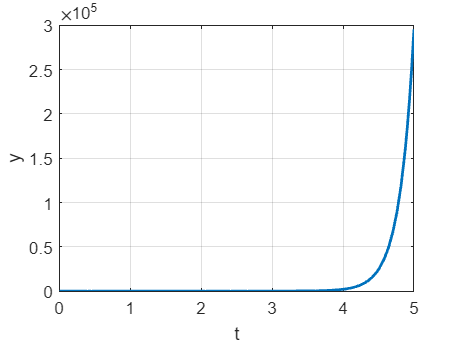

figure;

dy = @(t,y) 5*(y - t.^2);
[t,y] = ode45(dy,[0,5],0.08);
plot(t,y,'linewidth',1.5)
grid on
xlabel('t')
xlim([0, 5]);
ylabel('y')

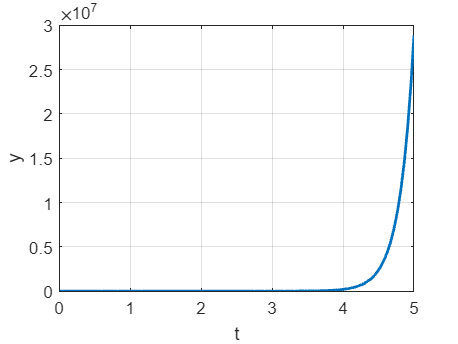


[t,y] = ode23s(dy,[0,5],0.08);
plot(t,y,'linewidth',1.5)
grid on
xlabel('t')
xlim([0, 5]);
ylabel('y');

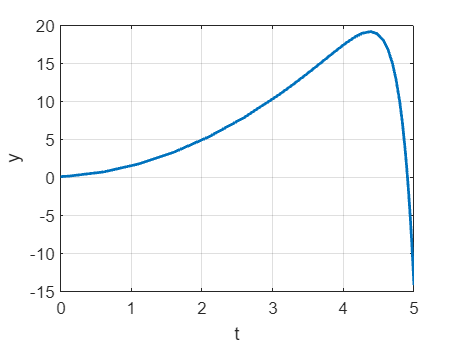


[t,y] = ode23tb(dy,[0,5],0.08);
plot(t,y,'linewidth',1.5)
grid on
xlabel('t')
xlim([0, 5]);
ylabel('y')

function dydt = freefall(t,y,cd,m)
% y(1) = x and y(2) = v
grav = 9.81;
dydt = [y(2);grav-cd/m*y(2)*abs(y(2))];
